## Задание 4. Синтез H_ထ-регулятора по выходу.

Начальные условия на задание:

A = [0 1;
     0 0]

A =      0     1
     0     0


B = [0; 1]

B =      0
     1


C = [1 0;]

C =      1     0


D = [0]

D = 0


Dw = [0 1]

Dw =      0     1


Bw = [0 0 ; 
      1 0]

Bw =      0     0
     1     0


eig(A)

ans =      0
     0


**Настройка моделирования**

simTimeStart = 0;
simTimeEnd = 10;
step = 0.0001; 
time = (simTimeStart:step:simTimeEnd)';

data.time= time;
modelName = 'model_observer_controller_noise'; 
load_system(modelName);

## **1- Первый набор Cz, Dz**

Cz = [1, 0;  
      0, 0]; 
Dz = [0;     
      2];  

% Проверка независимости
Cz'*Dz % == 0

ans =      0
     0


Bw*Dw' % == 0

ans =      0
     0


% Проверка невырожденности
Dw*Dw' % == scalar number

ans = 1

Dz'*Dz % == scalar number

ans = 4


% y = ampl * sin(w*t + phi)
ampl = [1 1];
phi = [pi/2 pi/2];
f = 5.2;
w = [2*pi * f 2*pi * f];

### **Рандомная частота у внешнего возмущения**

gamma = 20

gamma = 20

E = eye(size(A)); 
S = zeros(size(B));
%%%%
[P, ~, ~] = icare(A', C', (Bw * Bw') , Dw * Dw' , S, E, (1 / gamma^2) * (Cz' * Cz))

P =     1.4169    1.0013
    1.0013    1.4151


% Solve the Riccatis together...
[Q, ~, ~] = icare(A, B, (Cz' * Cz)  , Dz' * Dz , S, E, (1 / gamma^2) * (Bw * Bw') )

Q =     2.0050    2.0101
    2.0101    4.0303


% GET OBSERVE
L = -P * (eye(size(A)) - (1 / gamma^2)*Q*P)^-1 * (C + (1 / gamma^2)*Dw*Bw'*Q)' * (Dw * Dw')^-1

L =    -1.4524
   -1.0389


EIG_L =  eig(A + L*C)

EIG_L =   -0.7262 + 0.7152i
  -0.7262 - 0.7152i


mat2tex(L,2);

\begin{bmatrix}
    -1.45 \\
    -1.04 \\
\end{bmatrix}


% GET CONTROL
K = -inv( Dz' * Dz) * B' * Q

K =    -0.5025   -1.0076


EIG_K =  eig(A + B * K) 

EIG_K =   -0.5038 + 0.4987i
  -0.5038 - 0.4987i


mat2tex(K,2);

\begin{bmatrix}
    -0.5 & -1.01 \\
\end{bmatrix}


%%%___________%%%
%  Проверим условие согласованности !!!
disp(strcat(num2str(max(eig(P*Q))), " < ", num2str(gamma^2)))

12.2383 < 400


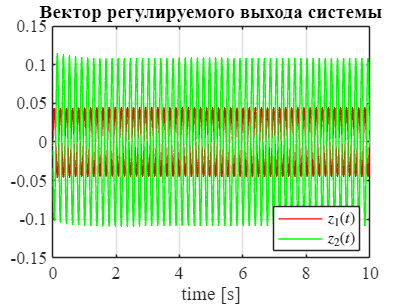

%%%___________%%%

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
x_obsv = out.x_obsv.Data;
error = out.out_error.Data;
z = out.z_plant.Data;


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, z(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, z(:,2), 'g', 'LineWidth', 1.0); grid on;
xlabel('time [s]');                                   
legend('$z_1(t)$','$z_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор регулируемого выхода системы');
save_file("z17");

### **Наихудший в каком-то смысле**

% y = ampl * sin(w*t + phi)
ampl = [1 1];
phi = [pi/2 pi/2];
f = 0.51;
w = [2*pi * f 2*pi * f];

E = eye(size(A)); 
S = zeros(size(B));
%%%%
[P, ~, ~] = icare(A', C', (Bw * Bw') , Dw * Dw' , S, E, (1 / gamma^2) * (Cz' * Cz))

P =     1.4169    1.0013
    1.0013    1.4151


% Solve the Riccatis together...
[Q, ~, ~] = icare(A, B, (Cz' * Cz)  , Dz' * Dz , S, E, (1 / gamma^2) * (Bw * Bw') )

Q =     2.0050    2.0101
    2.0101    4.0303



% GET OBSERVE
L = -P * (eye(size(A)) - (1 / gamma^2)*Q*P)^-1 * (C + (1 / gamma^2)*Dw*Bw'*Q)' * (Dw * Dw')^-1

L =    -1.4524
   -1.0389


EIG_L =  eig(A + L*C)

EIG_L =   -0.7262 + 0.7152i
  -0.7262 - 0.7152i


mat2tex(L,2);

\begin{bmatrix}
    -1.45 \\
    -1.04 \\
\end{bmatrix}


% GET CONTROL
K = -inv( Dz' * Dz) * B' * Q

K =    -0.5025   -1.0076


EIG_K =  eig(A + B * K) 

EIG_K =   -0.5038 + 0.4987i
  -0.5038 - 0.4987i


mat2tex(K,2);

\begin{bmatrix}
    -0.5 & -1.01 \\
\end{bmatrix}


%%%___________%%%
%  Проверим условие согласованности !!!
disp(strcat(num2str(max(eig(P*Q))), " < ", num2str(gamma^2)))

12.2383 < 400


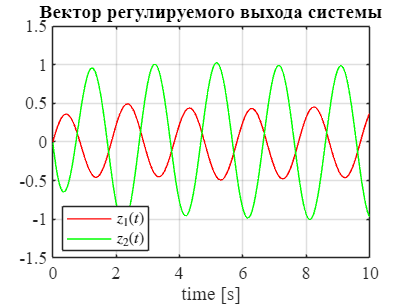

%%%___________%%%

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
x_obsv = out.x_obsv.Data;
error = out.out_error.Data;
z = out.z_plant.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, z(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, z(:,2), 'g', 'LineWidth', 1.0); grid on;
xlabel('time [s]');                                   
legend('$z_1(t)$','$z_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор регулируемого выхода системы');
save_file("z18");

s = tf('s');
sys = (Cz + Dz*K)*(s*eye(size(A)) - A - B*K)^-1 * Bw

sys =
 
  From input 1 to output...
                 1
   1:  ----------------------
       s^2 + 1.008 s + 0.5025
 
         -2.015 s^3 - 3.035 s^2 - 2.025 s - 0.5051
   2:  ---------------------------------------------
       s^4 + 2.015 s^3 + 2.02 s^2 + 1.013 s + 0.2525
 
  From input 2 to output...
   1:  0
 
   2:  0
 
Continuous-time transfer function.
Model Properties


disp(tf2latex(sys));

\begin{bmatrix}\frac{1}{1s^{2} + 1.01s + 0.5} & 0 \\\\ \frac{-2.02s^{3} - 3.04s^{2} - 2.03s - 0.51}{1s^{4} + 2.02s^{3} + 2.02s^{2} + 1.01s + 0.25} & 0\end{bmatrix}


tfs = {sys(1,1), sys(2,1)};
titles = {'in1→out',  'in2→out'};

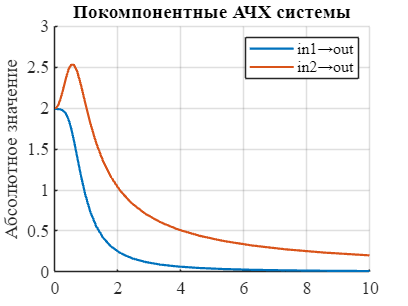

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
colors = lines(2);
hold on;
for i = 1:2
    [mag, ~, wout] = bode(tfs{i}, {0.001,10});
    plot(wout, squeeze(mag), 'Color', colors(i,:), 'LineWidth', 1.5);
end
legend(titles);
grid on;
ylabel('Абсолютное значение');
title("Покомпонентные АЧХ системы")
save_file("freq_ampl_components9");

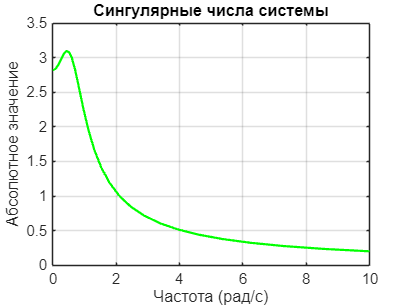

[sv, wout] = sigma(sys(:,1), {0.001,10});  % sv - массив сингулярных чисел (абсолютные значения)
sv = squeeze(sv);        

% Строим график
figure;
plot(wout, sv, 'g', 'LineWidth', 1.5);  
title('Сингулярные числа системы');
xlabel('Частота (рад/с)');
ylabel('Абсолютное значение');
grid on;
save_file("singular_values9");

% Вычисление H_2 и H_inf норм
H2_norm = norm(sys, 2) % H2_norm = sqrt(trace(Bw'*P*Bw))

H2_norm = 2.0000

H_inf_norm = norm(sys, inf)

H_inf_norm = 3.0956

## **Вторая гамма**

gamma = 6.0

gamma = 6

### **Рандомная частота у внешнего возмущения**

% y = ampl * sin(w*t + phi)
ampl = [1 1];
phi = [pi/2 pi/2];
f = 3.5;
w = [2*pi * f 2*pi * f];

E = eye(size(A)); 
S = zeros(size(B));
%%%%
[P, ~, ~] = icare(A', C', (Bw * Bw') , Dw * Dw' , S, E, (1 / gamma^2) * (Cz' * Cz))

P =     1.4444    1.0142
    1.0142    1.4242


% Solve the Riccatis together...
[Q, ~, ~] = icare(A, B, (Cz' * Cz)  , Dz' * Dz , S, E, (1 / gamma^2) * (Bw * Bw') )

Q =     2.0598    2.1213
    2.1213    4.3694



% GET OBSERVE
L = -P * (eye(size(A)) - (1 / gamma^2)*Q*P)^-1 * (C + (1 / gamma^2)*Dw*Bw'*Q)' * (Dw * Dw')^-1

L =    -2.0994
   -1.7100


EIG_L =  eig(A + L*C)

EIG_L =   -1.0497 + 0.7798i
  -1.0497 - 0.7798i


mat2tex(L,2);

\begin{bmatrix}
    -2.1 \\
    -1.71 \\
\end{bmatrix}


% GET CONTROL
K = -inv( Dz' * Dz) * B' * Q

K =    -0.5303   -1.0924


EIG_K =  eig(A + B * K) 

EIG_K =   -0.5462 + 0.4817i
  -0.5462 - 0.4817i


mat2tex(K,2);

\begin{bmatrix}
    -0.53 & -1.09 \\
\end{bmatrix}


%%%___________%%%
%  Проверим условие согласованности !!!
disp(strcat(num2str(max(eig(P*Q))), " < ", num2str(gamma^2)))

13.1489 < 36


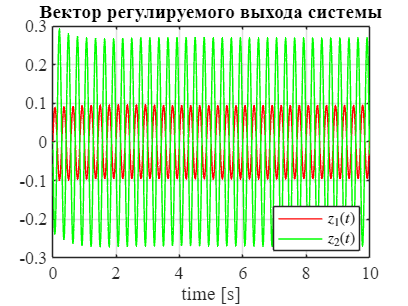

%%%___________%%%

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
x_obsv = out.x_obsv.Data;
error = out.out_error.Data;
z = out.z_plant.Data;


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, z(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, z(:,2), 'g', 'LineWidth', 1.0); grid on;
xlabel('time [s]');                                   
legend('$z_1(t)$','$z_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор регулируемого выхода системы');
save_file("z19");

### **Наихудший в каком-то смысле**

% y = ampl * sin(w*t + phi)
ampl = [1 1];
phi = [pi/2 pi/2];
f = 0.44;
w = [2*pi * f 2*pi * f];

E = eye(size(A)); 
S = zeros(size(B));
%%%%
[P, ~, ~] = icare(A', C', (Bw * Bw') , Dw * Dw' , S, E, (1 / gamma^2) * (Cz' * Cz))

P =     1.4444    1.0142
    1.0142    1.4242


% Solve the Riccatis together...
[Q, ~, ~] = icare(A, B, (Cz' * Cz)  , Dz' * Dz , S, E, (1 / gamma^2) * (Bw * Bw') )

Q =     2.0598    2.1213
    2.1213    4.3694



% GET OBSERVE
L = -P * (eye(size(A)) - (1 / gamma^2)*Q*P)^-1 * (C + (1 / gamma^2)*Dw*Bw'*Q)' * (Dw * Dw')^-1

L =    -2.0994
   -1.7100


EIG_L =  eig(A + L*C)

EIG_L =   -1.0497 + 0.7798i
  -1.0497 - 0.7798i


mat2tex(L,2);

\begin{bmatrix}
    -2.1 \\
    -1.71 \\
\end{bmatrix}


% GET CONTROL
K = -inv( Dz' * Dz) * B' * Q

K =    -0.5303   -1.0924


EIG_K =  eig(A + B * K) 

EIG_K =   -0.5462 + 0.4817i
  -0.5462 - 0.4817i


mat2tex(K,2);

\begin{bmatrix}
    -0.53 & -1.09 \\
\end{bmatrix}


%%%___________%%%
%  Проверим условие согласованности !!!
disp(strcat(num2str(max(eig(P*Q))), " < ", num2str(gamma^2)))

13.1489 < 36


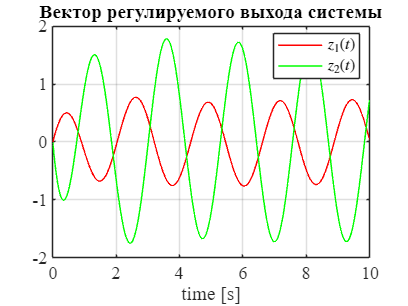

%%%___________%%%

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
x_obsv = out.x_obsv.Data;
error = out.out_error.Data;
z = out.z_plant.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, z(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, z(:,2), 'g', 'LineWidth', 1.0); grid on;
xlabel('time [s]');                                   
legend('$z_1(t)$','$z_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор регулируемого выхода системы');
save_file("z20");

s = tf('s');
sys = (Cz + Dz*K)*(s*eye(size(A)) - A - B*K)^-1 * Bw

sys =
 
  From input 1 to output...
                 1
   1:  ----------------------
       s^2 + 1.092 s + 0.5303
 
         -2.185 s^3 - 3.447 s^2 - 2.317 s - 0.5625
   2:  ----------------------------------------------
       s^4 + 2.185 s^3 + 2.254 s^2 + 1.159 s + 0.2812
 
  From input 2 to output...
   1:  0
 
   2:  0
 
Continuous-time transfer function.
Model Properties


disp(tf2latex(sys));

\begin{bmatrix}\frac{1}{1s^{2} + 1.09s + 0.53} & 0 \\\\ \frac{-2.18s^{3} - 3.45s^{2} - 2.32s - 0.56}{1s^{4} + 2.18s^{3} + 2.25s^{2} + 1.16s + 0.28} & 0\end{bmatrix}


tfs = {sys(1,1), sys(2,1)};
titles = {'in1→out',  'in2→out'};

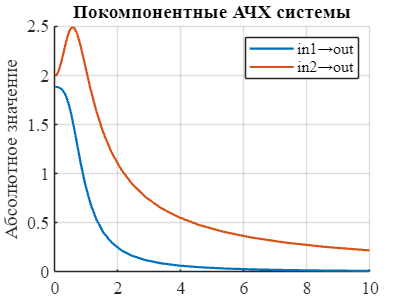

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
colors = lines(2);
hold on;
for i = 1:2
    [mag, ~, wout] = bode(tfs{i}, {0.001,10});
    plot(wout, squeeze(mag), 'Color', colors(i,:), 'LineWidth', 1.5);
end
legend(titles);
grid on;
ylabel('Абсолютное значение');
title("Покомпонентные АЧХ системы")
save_file("freq_ampl_components10");

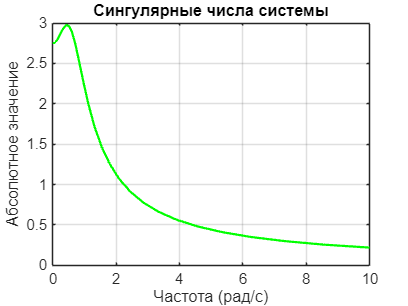

[sv, wout] = sigma(sys(:,1), {0.001,10});  % sv - массив сингулярных чисел (абсолютные значения)
sv = squeeze(sv);        

% Строим график
figure;
plot(wout, sv, 'g', 'LineWidth', 1.5);  
title('Сингулярные числа системы');
xlabel('Частота (рад/с)');
ylabel('Абсолютное значение');
grid on;
save_file("singular_values10");

% Вычисление H_2 и H_inf норм
H2_norm = norm(sys, 2) % H2_norm = sqrt(trace(Bw'*P*Bw))

H2_norm = 2.0047

H_inf_norm = norm(sys, inf)

H_inf_norm = 2.9758

**Функция, чтобы сохранить картинку в папку**

function save_file(name)
    path = 'D:\Math\control_theory\control_theory_labs\lab11\latex11\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');

end